# Sensitivity example computation

## Prof Joseph Morlier, ISAE-SUPAERO

## Clean up


%clear workspace
clear all;
%clear command window
clc;
%clear figures
clf;

## Define symbolic quantities

syms k_1 k_2
syms u_1 u_2
syms p_1 p_2
%the derived quantities will automatically be initialized as symbolic variables as well

Let's try to solve the sensitivies computation of this mechanical system. 

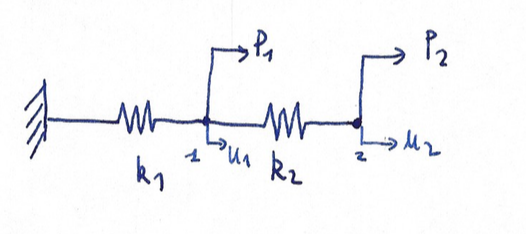

Of course it should respect the equilibrium Ku=P

## Static equilibrium

K=[k_1+k_2 -k_2; -k_2 k_2]

$$K = \left(\begin{array}{cc} k_{1}+k_{2} & -k_{2}\\ -k_{2} & k_{2} \end{array}\right)$$

U=[u_1; u_2]

$$U = \left(\begin{array}{c} u_{1}\\ u_{2} \end{array}\right)$$

P=[p_1;p_2]

$$P = \left(\begin{array}{c} p_{1}\\ p_{2} \end{array}\right)$$

1/Let's start by computing theses sensitivities using 

# SYMBOLIC COMPUTATION (remember previous variables: syms)

U0=K\P

$$U0 = \left(\begin{array}{c} \frac{p_{1}+p_{2}}{k_{1}}\\ \frac{k_{1}\,p_{2}+k_{2}\,p_{1}+k_{2}\,p_{2}}{k_{1}\,k_{2}} \end{array}\right)$$

U01=simplify(U0(1))

$$U01 = \frac{p_{1}+p_{2}}{k_{1}}$$


U02=simplify(U0(2))

$$U02 = \frac{k_{1}\,p_{2}+k_{2}\,p_{1}+k_{2}\,p_{2}}{k_{1}\,k_{2}}$$

F=(P(1)*U0(1)+P(2)*U0(2))

$$F = \frac{p_{1}\,\left(p_{1}+p_{2}\right)}{k_{1}}+\frac{p_{2}\,\left(k_{1}\,p_{2}+k_{2}\,p_{1}+k_{2}\,p_{2}\right)}{k_{1}\,k_{2}}$$

gradF_k1=simplify(diff(F,k_1))

$$gradF\_k1 = -\frac{{\left(p_{1}+p_{2}\right)}^{2}}{{k_{1}}^{2}}$$

gradF_k2=simplify(diff(F,k_2))

$$gradF\_k2 = -\frac{{p_{2}}^{2}}{{k_{2}}^{2}}$$

gradU_k1=diff(U0,k_1)

$$gradU\_k1 = \left(\begin{array}{c} -\frac{p_{1}+p_{2}}{{k_{1}}^{2}}\\ \frac{p_{2}}{k_{1}\,k_{2}}-\frac{k_{1}\,p_{2}+k_{2}\,p_{1}+k_{2}\,p_{2}}{{k_{1}}^{2}\,k_{2}} \end{array}\right)$$

gradU_k2=diff(U0,k_2)

$$gradU\_k2 = \left(\begin{array}{c} 0\\ \frac{p_{1}+p_{2}}{k_{1}\,k_{2}}-\frac{k_{1}\,p_{2}+k_{2}\,p_{1}+k_{2}\,p_{2}}{k_{1}\,{k_{2}}^{2}} \end{array}\right)$$

Numerical applications: $k_1=1$; $k_2=2$, $p_1=1$, $p_2=2$

gFk1=subs(gradF_k1,{k_1,k_2,p_1,p_2},{1,2,1,2})

$$gFk1 = -9$$

gFk2=subs(gradF_k2,{k_1,k_2,p_1,p_2},{1,2,1,2})

$$gFk2 = -1$$

gUk1=subs(gradU_k1,{k_1,k_2,p_1,p_2},{1,2,1,2})

$$gUk1 = \left(\begin{array}{c} -3\\ -3 \end{array}\right)$$

gUk2=subs(gradU_k2,{k_1,k_2,p_1,p_2},{1,2,1,2})

$$gUk2 = \left(\begin{array}{c} 0\\ -\frac{1}{2} \end{array}\right)$$

2/Now we need to compute theses sensitivities by 

# FD (Finite Differences)

dx1=1e-6; % you can change this for evaluating the table unknwonws (see exercice)
dx2=dx1;
Kdx1=[k_1+dx1+k_2 -k_2; -k_2 k_2]

$$Kdx1 = \left(\begin{array}{cc} k_{1}+k_{2}+\frac{1}{1000000} & -k_{2}\\ -k_{2} & k_{2} \end{array}\right)$$

Kdx2=[k_1+k_2+dx2 -k_2-dx2; -k_2-dx2 k_2+dx2]

$$Kdx2 = \left(\begin{array}{cc} k_{1}+k_{2}+\frac{1}{1000000} & -k_{2}-\frac{1}{1000000}\\ -k_{2}-\frac{1}{1000000} & k_{2}+\frac{1}{1000000} \end{array}\right)$$

U1=Kdx1\P

$$U1 = \left(\begin{array}{c} \frac{1000000\,\left(p_{1}+p_{2}\right)}{1000000\,k_{1}+1}\\ \frac{p_{2}+1000000\,k_{1}\,p_{2}+1000000\,k_{2}\,p_{1}+1000000\,k_{2}\,p_{2}}{k_{2}\,\left(1000000\,k_{1}+1\right)} \end{array}\right)$$

U2=Kdx2\P

$$U2 = \left(\begin{array}{c} \frac{p_{1}+p_{2}}{k_{1}}\\ \frac{p_{1}+p_{2}+1000000\,k_{1}\,p_{2}+1000000\,k_{2}\,p_{1}+1000000\,k_{2}\,p_{2}}{k_{1}+1000000\,k_{1}\,k_{2}} \end{array}\right)$$

F=(P(1)*U0(1)+P(2)*U0(2))

$$F = \frac{p_{1}\,\left(p_{1}+p_{2}\right)}{k_{1}}+\frac{p_{2}\,\left(k_{1}\,p_{2}+k_{2}\,p_{1}+k_{2}\,p_{2}\right)}{k_{1}\,k_{2}}$$

Fdx1=(P(1)*U1(1)+P(2)*U1(2))

$$Fdx1 = \frac{1000000\,p_{1}\,\left(p_{1}+p_{2}\right)}{1000000\,k_{1}+1}+\frac{p_{2}\,\left(p_{2}+1000000\,k_{1}\,p_{2}+1000000\,k_{2}\,p_{1}+1000000\,k_{2}\,p_{2}\right)}{k_{2}\,\left(1000000\,k_{1}+1\right)}$$

Fdx2=(P(1)*U2(1)+P(2)*U2(2))

$$Fdx2 = \frac{p_{2}\,\left(p_{1}+p_{2}+1000000\,k_{1}\,p_{2}+1000000\,k_{2}\,p_{1}+1000000\,k_{2}\,p_{2}\right)}{k_{1}+1000000\,k_{1}\,k_{2}}+\frac{p_{1}\,\left(p_{1}+p_{2}\right)}{k_{1}}$$

gFk1_FD= (Fdx1-F)/dx1

$$gFk1\_FD = \frac{1000000000000\,p_{1}\,\left(p_{1}+p_{2}\right)}{1000000\,k_{1}+1}-\frac{1000000\,p_{1}\,\left(p_{1}+p_{2}\right)}{k_{1}}-\frac{1000000\,p_{2}\,\left(k_{1}\,p_{2}+k_{2}\,p_{1}+k_{2}\,p_{2}\right)}{k_{1}\,k_{2}}+\frac{1000000\,p_{2}\,\left(p_{2}+1000000\,k_{1}\,p_{2}+1000000\,k_{2}\,p_{1}+1000000\,k_{2}\,p_{2}\right)}{k_{2}\,\left(1000000\,k_{1}+1\right)}$$

gFk2_FD= (Fdx2-F)/dx2

$$gFk2\_FD = \frac{1000000\,p_{2}\,\left(p_{1}+p_{2}+1000000\,k_{1}\,p_{2}+1000000\,k_{2}\,p_{1}+1000000\,k_{2}\,p_{2}\right)}{k_{1}+1000000\,k_{1}\,k_{2}}-\frac{1000000\,p_{2}\,\left(k_{1}\,p_{2}+k_{2}\,p_{1}+k_{2}\,p_{2}\right)}{k_{1}\,k_{2}}$$

gFk1_FD=eval(subs(gFk1_FD,{k_1,k_2,p_1,p_2},{1,2,1,2}))

gFk1_FD = -9.0000

gFk2_FD=eval(subs(gFk2_FD,{k_1,k_2,p_1,p_2},{1,2,1,2}))

gFk2_FD = -1.0000

Please double click on the workspace value of  -8.999991000009000 for gFk1_FD and -0.999999500000250 for gFk2_FD (WARNING DOUBLE /SINGLE PRECISION)

3/ Now we need to compute theses sensitivities by 

# DIRECT METHOD

invK=inv(K)

$$invK = \left(\begin{array}{cc} \frac{1}{k_{1}} & \frac{1}{k_{1}}\\ \frac{1}{k_{1}} & \frac{k_{1}+k_{2}}{k_{1}\,k_{2}} \end{array}\right)$$

dK_k1=diff(K,k_1)

$$dK\_k1 = \left(\begin{array}{cc} 1 & 0\\ 0 & 0 \end{array}\right)$$

dK_k2=diff(K,k_2)

$$dK\_k2 = \left(\begin{array}{cc} 1 & -1\\ -1 & 1 \end{array}\right)$$

dP_k1=diff(P,k_1)

$$dP\_k1 = \left(\begin{array}{c} 0\\ 0 \end{array}\right)$$

dP_k2=diff(P,k_2)

$$dP\_k2 = \left(\begin{array}{c} 0\\ 0 \end{array}\right)$$

gUk1_DM=invK*(dP_k1-diff(K,k_1)*U0)

$$gUk1\_DM = \left(\begin{array}{c} -\frac{p_{1}+p_{2}}{{k_{1}}^{2}}\\ -\frac{p_{1}+p_{2}}{{k_{1}}^{2}} \end{array}\right)$$

gUk2_DM=invK*(dP_k2-diff(K,k_2)*U0)

$$gUk2\_DM = \left(\begin{array}{c} 0\\ \frac{\left(k_{1}+k_{2}\right)\,\left(\frac{p_{1}+p_{2}}{k_{1}}-\frac{k_{1}\,p_{2}+k_{2}\,p_{1}+k_{2}\,p_{2}}{k_{1}\,k_{2}}\right)}{k_{1}\,k_{2}}-\frac{\frac{p_{1}+p_{2}}{k_{1}}-\frac{k_{1}\,p_{2}+k_{2}\,p_{1}+k_{2}\,p_{2}}{k_{1}\,k_{2}}}{k_{1}} \end{array}\right)$$

gFk1_DM=P'*gUk1_DM

$$gFk1\_DM = -\frac{\bar{p_{1}}\,\left(p_{1}+p_{2}\right)}{{k_{1}}^{2}}-\frac{\bar{p_{2}}\,\left(p_{1}+p_{2}\right)}{{k_{1}}^{2}}$$

gFk2_DM=P'*gUk2_DM

$$gFk2\_DM = -\bar{p_{2}}\,\left(\frac{\frac{p_{1}+p_{2}}{k_{1}}-\frac{k_{1}\,p_{2}+k_{2}\,p_{1}+k_{2}\,p_{2}}{k_{1}\,k_{2}}}{k_{1}}-\frac{\left(k_{1}+k_{2}\right)\,\left(\frac{p_{1}+p_{2}}{k_{1}}-\frac{k_{1}\,p_{2}+k_{2}\,p_{1}+k_{2}\,p_{2}}{k_{1}\,k_{2}}\right)}{k_{1}\,k_{2}}\right)$$

gFk1_DM=eval(subs(gFk1_DM,{k_1,k_2,p_1,p_2},{1,2,1,2}))

gFk1_DM = -9

gFk2_DM=eval(subs(gFk2_DM,{k_1,k_2,p_1,p_2},{1,2,1,2}))

gFk2_DM = -1

Which method is exact???

gFk1_DM==-9 

ans = logical
   1


gFk1_FD==-9

ans = logical
   0


gFk2_DM==-1 

ans = logical
   1


gFk2_FD==-1

ans = logical
   0
